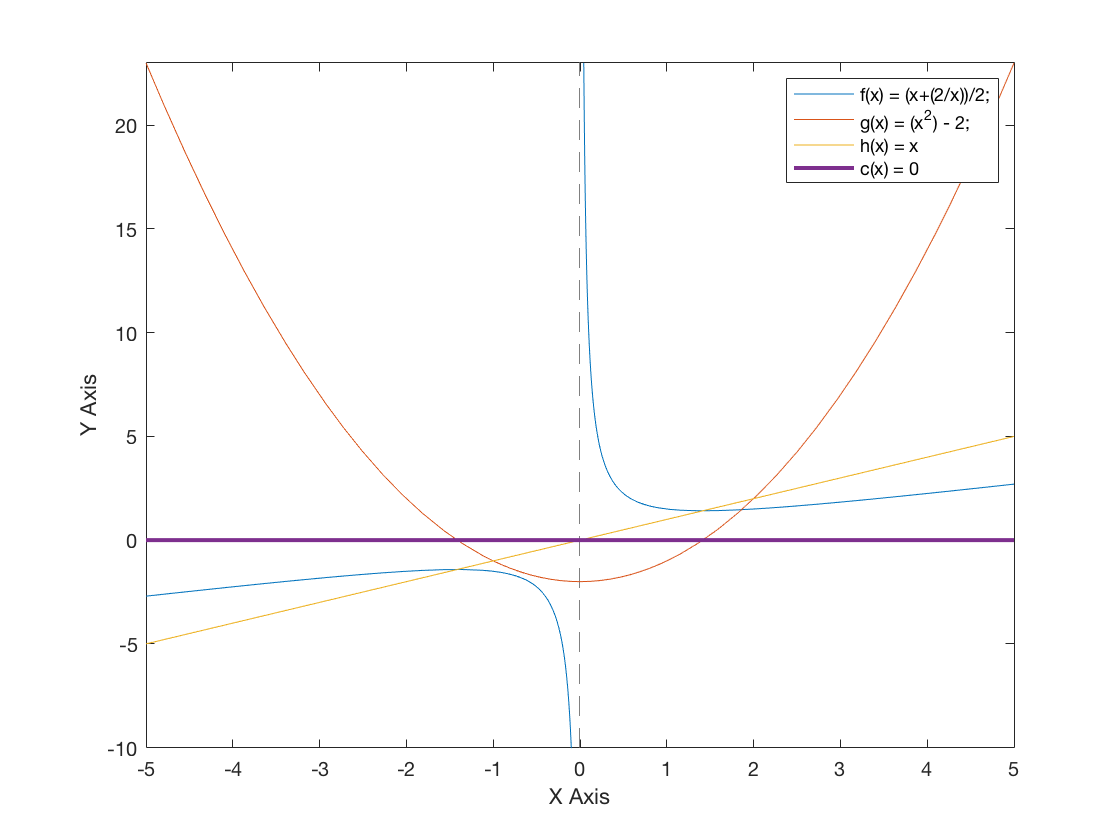

% Number (a).i
f = @(x) (x+(2./x))./2;
g = @(x) (x.^2) - 2;
h = @(x) x;
c = 0;
%The root of these two functions are the same
%We see an intersection at x = 2

fplot(f);
hold on;
fplot(g);
fplot(h);
fplot(c,'LineWidth',2)
hold off;

xlabel('X Axis');
ylabel('Y Axis');
legend('f(x) = (x+(2/x))/2;','g(x) = (x^2) - 2;','h(x) = x','c(x) = 0');


% Number (a).ii
% p0 will be + or - depening if p0 is + or -
% The more iterations, the more accurate it will be
fp(f, 1, 30)

We are on iteration: 6


ans = 1.4142

% fp(f, -1, 30)

% Number (a).iii
% Collaborated with Jhon for this problem
f = @(x) (x.^2-2);
g = @(x) (x+2/x)/2;
% fp(g, 1.5, 10)
% bisection(g,1,2,eps,100);

a = gPlot(g, 1.5, 100);
a_d = abs(sqrt(2)-a);
b = bisectionplot(f,1,2,eps,60);

Root is in the side 
Root is in the right side 
Root is in the right side 
Root is in the side 
Root is in the right side 
Root is in the side 
Root is in the right side 
Root is in the side 
Root is in the side 
Root is in the side 
Root is in the side 
Root is in the side 
Root is in the right side 
Root is in the side 
Root is in the side 
Root is in the right side 
Root is in the right side 
Root is in the right side 
Root is in the right side 
Root is in the side 
Root is in the side 
Root is in the right side 
Root is in the right side 
Root is in the side 
Root is in the side 
Root is in the right side 
Root is in the right side 
Root is in the side 
Root is in the side 
Root is in the right side 
Root is in the right side 
Root is in the right side 
Root is in the right side 
Root is in the right side 
Root is in the right side 
Root is in the right side 
Root is in the side 
Root is in the side 
Root is in the right side 
Root is in the right side 
Root is in the right side 
R

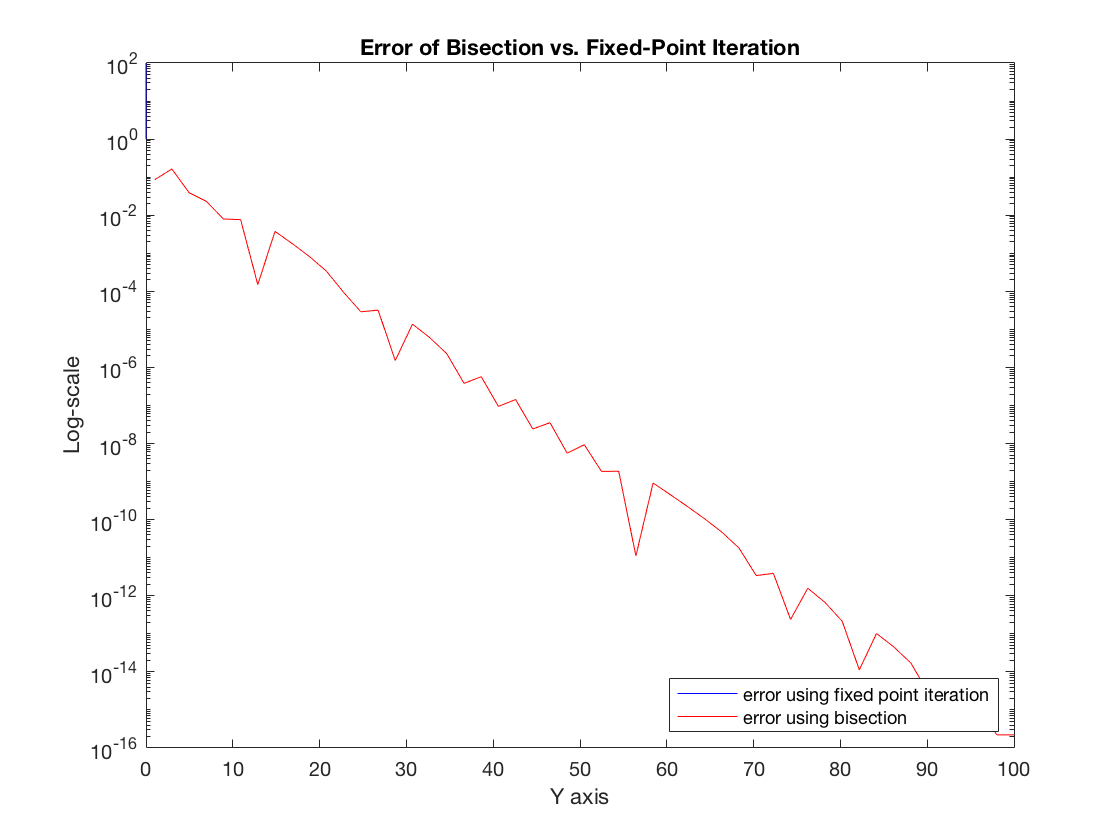

xO=linspace(1,100,100);
xP=linspace(1,100,51);

b_d = abs(sqrt(2)-b);
semilogy(a_d,xO,'b',xP,b_d,'r')

title('Error of Bisection vs. Fixed-Point Iteration')
legend('error using fixed point iteration','error using bisection','Location','southeast')
xlabel('Y axis')
ylabel('Log-scale')

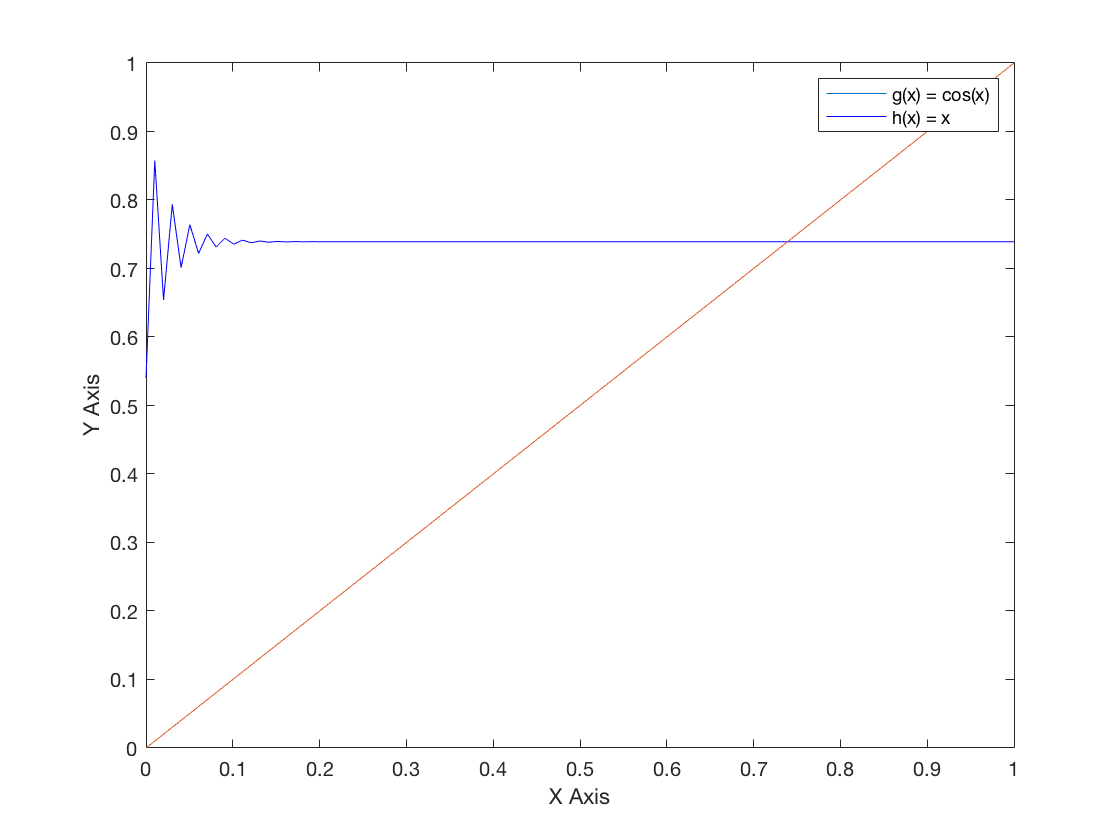

%Number (b).i
g = @(x) cos(x);
h = @(x) x;
x = linspace(0,1,100);
y = linspace(0,1,100);
xP = gPlot(g,1,100);
yP = gPlot(g,1,100);

plot(x,xP,y,yP,'b')
hold on 
plot(x,h(x))
hold off

xlabel('X Axis');
ylabel('Y Axis');
legend('g(x) = cos(x)', 'h(x) = x');

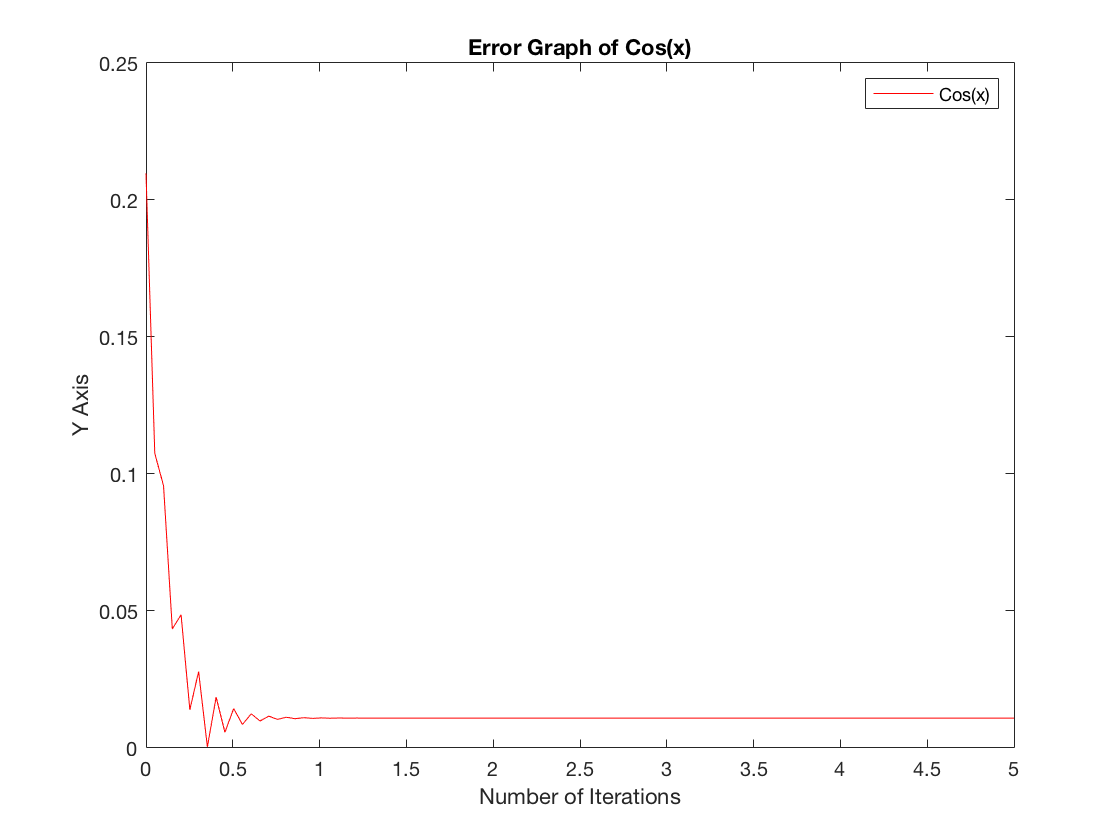


%Number (b).ii
xError = linspace(0,5,100);
yError = abs(.75-xP);
plot(xError,yError,'r');

title('Error Graph of Cos(x)');
legend('Cos(x)');
xlabel('Number of Iterations');
ylabel('Y Axis');

%Number (c).i
g = @(x) 2*x;
fp(g,0,5)

We are on iteration: 1


ans = 0

% To converge to 0, we need p0 to be 0 or near 0.
% Any other value will make it + or - Inf.

%Number (d).i
g = @(x) 2/x;
h = @(x) 1;
fp(g,1,10)

ans = 1

% Using the fp will never give us a fixed point value that we need
% For g, it will never coverge to 0 while for h, it will
% always converge to 1.


function p = fp(f, p0, maxits)
    i = 1;
    while (i <= maxits)
        p = f(p0);
        if(abs(p-p0) < eps())
           fprintf("We are on iteration: " + i + "\n");
           break;
        end
        i = i+1;
        p0 = p;  
    end
    p = p0;
end

function p_plot = gPlot(g, p0, maxits)
vec = zeros(1,maxits);
temp=0;
for i=1:maxits
    x=temp;
    temp= g(p0);
    p0=temp;
    vec(i) = p0; 
end
p_plot=vec;
end

function r = bisection(f,a,b,tol,maxits)
% Bisection method is used to find the root of a given value.
% f = The continuous function on [a,b]
% r = An approximation of a root for f on [a,b]
% tol = A bound for the desired accuracy.
% maxits = The maximum number of iterations
if f(a) == 0
    r=a;
    return;
else
    c= (a+b)/2;
    r=b;
end

x=0;
y=0;

for i = 1:maxits
    c= (a+b)/2;
    x(i)=i;
    y(i)=c;
    
        if f(c) == 0||(b-a)/2 <=tol
            r=c;
            break;
        end
r=c;

end
end

function r = bisectionplot(f,a,b,tol,maxits)
% Bisection method is used to find the root of a given value & returns all of the iterates.
% f = The continuous function on [a,b]
% r = An approximation of a root for f on [a,b]
% tol = A bound for the desired accuracy.
% maxits = The maximum number of iterations

assert(sign(f(a)) ~= sign(f(b)));
assert(a<b)
assert(~isinf(a)&&~isinf(b))

if f(a) == 0
    r=a;
    return;
else
    c= (a+b)/2;
    r=b;
end

x=0;
y=0;
vec = zeros(maxits,0);

for i = 1:maxits
    c= (a+b)/2;
    x(i)=i;
    y(i)=c;
    vec(i) = c;
    
    if f(c) == 0||(b-a)/2 <= tol
%         Cell_1 = {x y}
%         r=Cell_1;
        
        return;
    end
    if sign(f(c)) ~= sign(f(a))
        fprintf('Root is in the side \n');
        b = c;
    else
        fprintf('Root is in the right side \n')
        a = c;
    end
    if i == maxits
        warning('Maximum number of iterations')
    end
        
    r=vec;

end
end
